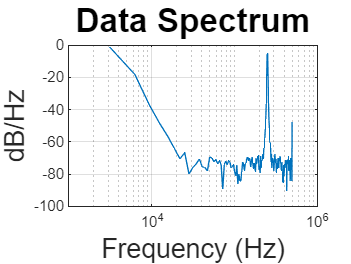

@Freq = 1586.914, SNR = 43.767 dB, SNDR = -1.638 dB, SFDR = 3.703 dB, HD2 = 3.703 and HD3 = 15.040


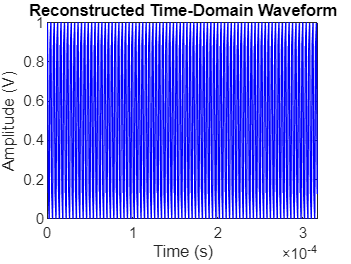

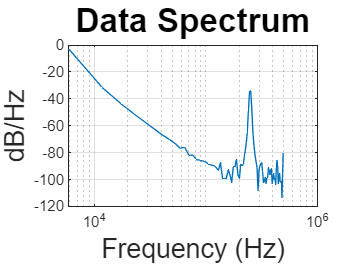

@Freq = 854.492, SNR = 39.101 dB, SNDR = -0.003 dB, SFDR = 8.585 dB, HD2 = 8.585 and HD3 = 23.490


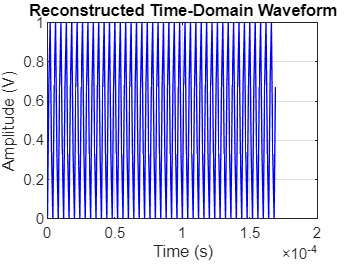

@Freq = 854.492, SNR = 39.101 dB, SNDR = -0.003 dB, SFDR = 8.585 dB, HD2 = 8.585 and HD3 = 23.490


@Freq = 1586.914, SNR = 43.767 dB, SNDR = -1.638 dB, SFDR = 3.703 dB, HD2 = 3.703 and HD3 = 15.040


@Freq = 1586.914, SNR = 43.767 dB, SNDR = -1.638 dB, SFDR = 3.703 dB, HD2 = 3.703 and HD3 = 15.040


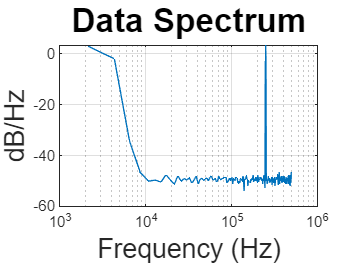

@Freq = 2319.336, SNR = 30.984 dB, SNDR = -4.121 dB, SFDR = 29.169 dB, HD2 = 29.169 and HD3 = 39.370


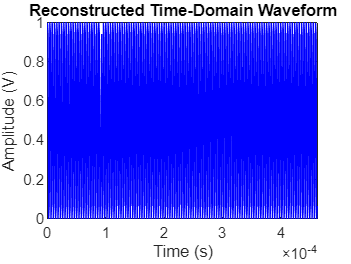

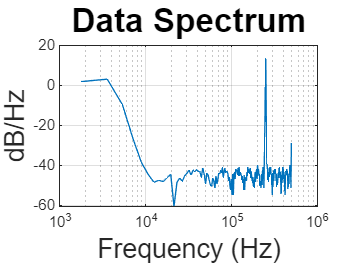

@Freq = 2807.617, SNR = 13.058 dB, SNDR = -13.708 dB, SFDR = 27.511 dB, HD2 = 27.511 and HD3 = 37.406


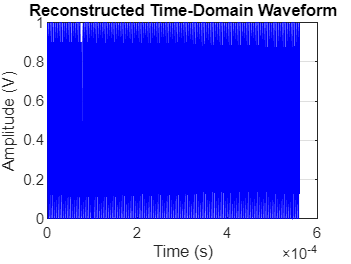

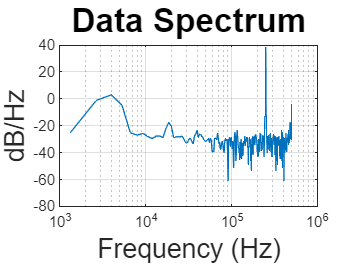

@Freq = 3784.180, SNR = 33.967 dB, SNDR = -38.190 dB, SFDR = 12.446 dB, HD2 = 12.446 and HD3 = 27.161


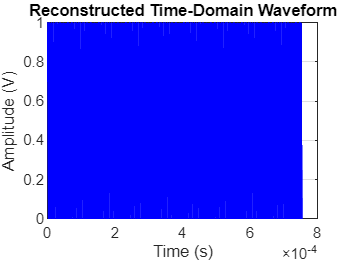

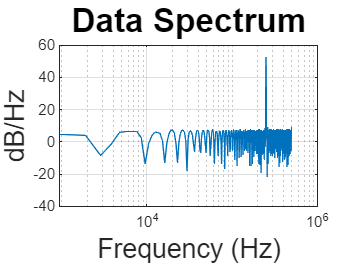

@Freq = 5249.023, SNR = 24.265 dB, SNDR = -52.776 dB, SFDR = 2.371 dB, HD2 = 2.371 and HD3 = 6.178


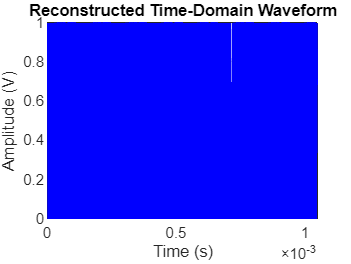

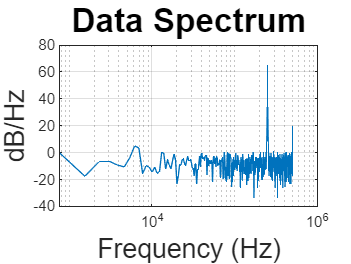

@Freq = 6469.727, SNR = 43.796 dB, SNDR = -65.677 dB, SFDR = 0.908 dB, HD2 = 0.908 and HD3 = 7.858


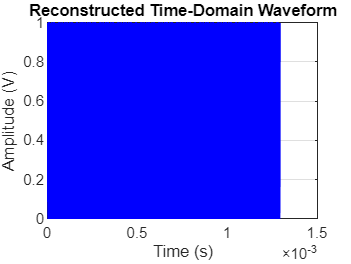

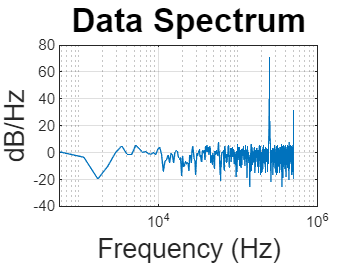

@Freq = 8666.992, SNR = 40.530 dB, SNDR = -72.418 dB, SFDR = -1.298 dB, HD2 = -1.298 and HD3 = 7.131


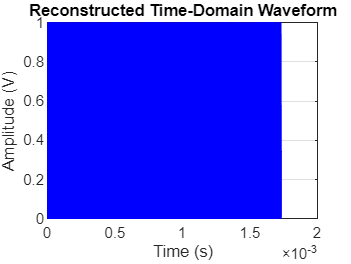

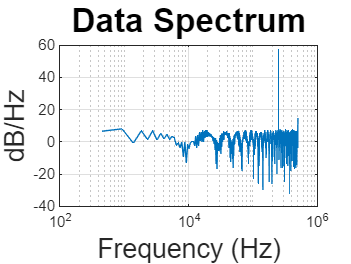

@Freq = 10864.258, SNR = 25.486 dB, SNDR = -56.102 dB, SFDR = -0.502 dB, HD2 = -0.502 and HD3 = 1.333


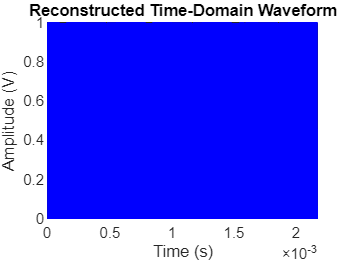

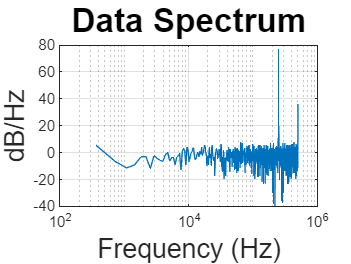

@Freq = 13793.945, SNR = 42.495 dB, SNDR = -77.974 dB, SFDR = -0.978 dB, HD2 = -0.978 and HD3 = -0.316


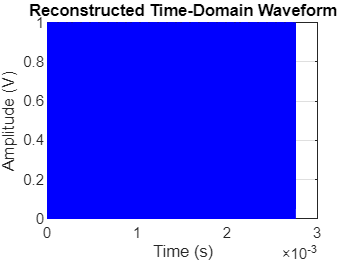

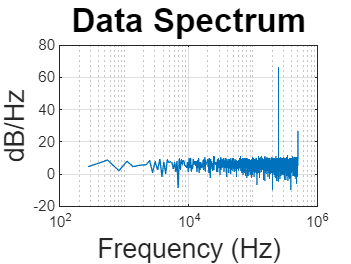

@Freq = 18188.477, SNR = 29.363 dB, SNDR = -67.101 dB, SFDR = -8.818 dB, HD2 = -8.818 and HD3 = -1.633


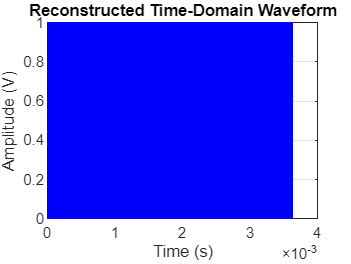

Error using zeros
Size inputs must be integers.

Error in plot_periodogram_SFDR (line 129)
f = zeros(1, periodogram_length/2);

clearvars
freq_array = readtable('./ADC_Data/CML-Data/4XCLK-2-12-2-EthanTBBoard3_BYPASS-Freq_1k_250k-SIN_1000mV-CLK_0MHz_Duty50%/freq_array.csv');
freq_array = table2array(freq_array);
%%% Remember to change this! if folder change
filepath = './ADC_Data/CML-Data/4XCLK-2-12-2-EthanTBBoard3_BYPASS-Freq_1k_250k-SIN_1000mV-CLK_0MHz_Duty50%/';
% 1:freq, 2: SNR, 3: SNDR 4:SFDR
BigSet = zeros(length(freq_array),4);
% :length(freq_array)
for i = 1:length(freq_array)
    freq = num2str(freq_array(i));
    BigSet(i,1) = freq_array(i);
    filename = strcat(filepath,'SIN_',num2str(freq_array(i)),'Hz_.csv');
    data = readtable(filename);
    data_dec = table2array(data);
    % data_dec = data_dec(data_dec ~= 0);
    data_bin = dec2bin(data_dec);
    data_EOC = str2num(data_bin(:,1));
    data_Code = str2num(data_bin(:,2:10));
    data_NewCode = size(length(data_Code),1);
    data_Code_dec = bin2dec(num2str(data_Code));

    rising_edge_indices = find(diff(data_EOC) == -1);
    time_diff = diff(rising_edge_indices);
    for k = 1:length(rising_edge_indices)
        index = rising_edge_indices(k);
        data_NewCode(k,1) = data_Code_dec(index);

    end
    data_NewDec = data_NewCode;
    % data_NewDec = floor(medfilt1(data_NewCode, 10));
    % data_NewDec = data_NewDec(1:5000);
    Fs=1e6;
    num_segments=1;
    f_signal = freq_array(i);
    f_s = Fs;
    BW =Fs/2;
    sample_size=length(data_NewDec);
    % sample_size=length(data_NewDec);
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
    BigSet(i,2) = SNR;
    BigSet(i,3) = SNDR;
    BigSet(i,4) = SFDR;
    
    %%%%%% Reconstructed the waveform
    % Parameters
    fs = 1e6;                 % Sampling rate in Hz
    N = length(data_NewDec);                  % Number of samples
    bit_depth = 9;            % ADC bit resolution
    V_min = 0;              % Minimum input voltage
    V_max = 1;               % Maximum input voltage
    
    % Map codes to voltage
    voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;
    
    % Create time axis
    t = (0:N-1) / fs;
    
    % Plot the reconstructed waveform
    figure;
    plot(t, voltages, 'b');
    title('Reconstructed Time-Domain Waveform');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

save('BigSet.mat', 'BigSet');

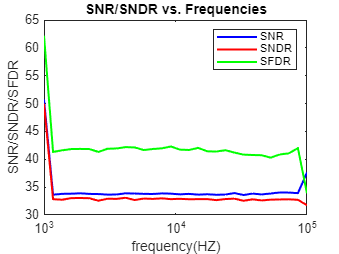

save('BigSet.mat', 'BigSet');
load('BigSet.mat')
figure
semilogx(BigSet(:,1), BigSet(:,2), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(BigSet(:,1), BigSet(:,3), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
semilogx(BigSet(:,1), BigSet(:,4), 'g-', 'LineWidth', 1.5, "DisplayName","SFDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR/SFDR");
title("SNR/SNDR vs. Frequencies");
legend;

% Detect crossings: Where signal crosses 0.5
threshold = 512/2;
crossing_indices = find((data_NewDec(1:end-1) < threshold & data_NewDec(2:end) >= threshold) | ...
                        (data_NewDec(1:end-1) >= threshold & data_NewDec(2:end) < threshold));

% Count crossings
num_crossings = length(crossing_indices);

% Display result
fprintf('Number of crossings: %d\n', num_crossings);

Number of crossings: 46
